# Preprocessing

                                                                                        animalNum = 196664;
                                                                                        estrusPhase = 'M';
                                                                                        lightCycle = 'L'; 
                                                                                        blDone = 15;        BLsec = blDone*60;
                                                                                        FsStart = 17;       FsStartSec = FsStart*60;
                                                                                        FsDone = 22;        FsDoneSec = FsDone*60;
                                                                                        ClonInject = 27;    ClonInjectSec = ClonInject*60;
                                                                                        clon25 = ClonInject+25;     clon25Sec =clon25*60;
                                                                                        clon30 = ClonInject+30;     clon30Sec = clon30*60;

colHeads = ["channel", "unit", "timestamp", "energy", "Area", "PeakFWHM", "ValleyFWHM", "PeakValley", "Waveforms>>"];
data = array2table([SPK01; SPK02; SPK03; SPK04; SPK05; SPK06; SPK07; SPK08; SPK09; SPK10; SPK11; SPK12; SPK13; SPK14; SPK15; SPK16]);
data.Properties.VariableNames(1:9) = colHeads;


waveforms = data(:,4:88);
data = removevars(data, [4:88]);

                                                                                        

estrusPhase = cellstr(estrusPhase);
lightCycle = cellstr(lightCycle);

% Add new columns with repeated values
data.animalNum = repmat(animalNum, height(data), 1);
data.estrusPhase = repmat(estrusPhase, height(data), 1);
data.lightCycle = repmat(lightCycle, height(data), 1);

data.unitID = strings(height(data), 1);  
data.unitID(data.animalNum == animalNum) = strcat(num2str(animalNum), '_', num2str(data.channel(data.animalNum == animalNum)), '_', num2str(data.unit(data.animalNum == animalNum)));

DataHeads = ["unitID", "estrusPhase", "lightCycle", "timestamp"];
Data = array2table([data.unitID, data. estrusPhase, data.lightCycle, data.timestamp]);
Data.Properties.VariableNames(1:4) = DataHeads;
Data.timestamp = str2double(Data.timestamp);

waveformData = [data, waveforms];

waveformFile = ['waveFormData', num2str(animalNum), '.mat'];
save(waveformFile, 'waveformData');

uniqueUnits = unique(Data.unitID);

#### Breaking up by epoch

BLSpikes = Data(Data.timestamp < BLsec, :);
FSSpikes = Data(Data.timestamp > FsStartSec & Data.timestamp < FsDoneSec, :);
clon25Spikes = Data(Data.timestamp > clon25Sec & Data.timestamp < clon30Sec, :);


# Spike Data-do this for each epoch

Baseline

measures = ["unitID", "ISI", "FiringRate", "SpikeNum"];
variableTypes = ["string", "double", "double", "double"];
uniqueUnits = unique(BLSpikes.unitID);
BLAves = table('Size', [length(uniqueUnits), length(measures)], 'VariableTypes', variableTypes, ...
              'VariableNames', measures);

%Baseline
for i = 1:length(uniqueUnits)
    unitData = BLSpikes(BLSpikes.unitID == uniqueUnits(i), :); 
    BLAves.unitID(i) = string(uniqueUnits(i));  % Ensure the unitID is treated as a string
    if ~isempty(unitData.timestamp)
        BLAves.ISI(i) = mean(diff(unitData.timestamp));
        if BLAves.ISI(i) > 0
            BLAves.FiringRate(i) = 1 / BLAves.ISI(i);  % Only calculate if ISI is positive
        else
            BLAves.FiringRate(i) = NaN;  % Avoid division by zero
        end
        BLAves.SpikeNum(i) = size(unitData, 1);  % Count of spikes
    else
        BLAves.ISI(i) = 0;  % Handle cases with no data
        BLAves.FiringRate(i) = 0;
        BLAves.SpikeNum(i) = 0;  % Assume no spikes if data is empty
    end
end


%FootShock
measures = ["unitID", "ISI", "FiringRate", "SpikeNum"];
variableTypes = ["string", "double", "double", "double"];
uniqueUnits = unique(FSSpikes.unitID);
FSAves = table('Size', [length(uniqueUnits), length(measures)], 'VariableTypes', variableTypes, ...
              'VariableNames', measures);

for i = 1:length(uniqueUnits)
    unitData = FSSpikes(FSSpikes.unitID == uniqueUnits(i), :); 
    FSAves.unitID(i) = string(uniqueUnits(i));  % Ensure the unitID is treated as a string
    if ~isempty(unitData.timestamp)
        FSAves.ISI(i) = mean(diff(unitData.timestamp));
        if FSAves.ISI(i) > 0
            FSAves.FiringRate(i) = 1 / FSAves.ISI(i);  % Only calculate if ISI is positive
        else
            FSAves.FiringRate(i) = NaN;  % Avoid division by zero
        end
        FSAves.SpikeNum(i) = size(unitData, 1);  % Count of spikes
    else
        FSAves.ISI(i) = 0;  % Handle cases with no data
        FSAves.FiringRate(i) = 0;
        FSAves.SpikeNum(i) = 0;  % Assume no spikes if data is empty
    end
end

%Clon25
uniqueUnits = unique(clon25Spikes.unitID);
Clon5Aves = table('Size', [length(uniqueUnits), length(measures)], 'VariableTypes', variableTypes, ...
              'VariableNames', measures);

for i = 1:length(uniqueUnits)
    unitData = clon25Spikes(clon25Spikes.unitID == uniqueUnits(i), :); 
    Clon5Aves.unitID(i) = string(uniqueUnits(i));  % Ensure the unitID is treated as a string
    if ~isempty(unitData.timestamp)
        Clon5Aves.ISI(i) = mean(diff(unitData.timestamp));
        if Clon5Aves.ISI(i) > 0
            Clon5Aves.FiringRate(i) = 1 / Clon5Aves.ISI(i);  % Only calculate if ISI is positive
        else
            Clon5Aves.FiringRate(i) = NaN;  % Avoid division by zero
        end
        Clon5Aves.SpikeNum(i) = size(unitData, 1);  % Count of spikes
    else
        Clon5Aves.ISI(i) = 0;  % Handle cases with no data
        Clon5Aves.FiringRate(i) = 0;
        Clon5Aves.SpikeNum(i) = 0;  % Assume no spikes if data is empty
    end
end


NA Determine

% Create the epochByUnit table with the unitID column
epochByUnit = table(unique([BLAves.unitID; FSAves.unitID; Clon5Aves.unitID]), 'VariableNames', {'unitID'});

% Loop through each unitID
for i = 1:size(epochByUnit, 1)
    unitID = epochByUnit.unitID(i);

    % Find the corresponding values in each table
    blValue = BLAves.FiringRate(BLAves.unitID == unitID);
    fsValue = FSAves.FiringRate(FSAves.unitID == unitID);
    clonValue = Clon5Aves.FiringRate(Clon5Aves.unitID == unitID);

    % Check if the values are empty and assign 0 if they are
    if isempty(blValue)
        blValue = 0;
    end
    if isempty(fsValue)
        fsValue = 0;
    end
    if isempty(clonValue)
        clonValue = 0;
    end

    % Add the values to the epochByUnit table
    epochByUnit.BLFR(i) = blValue;
    epochByUnit.FSFR(i) = fsValue;
    epochByUnit.ClonFR(i) = clonValue;
end

for k = 1:width(epochByUnit)
    if isnumeric(epochByUnit{:,k})  % Check if the column is numeric
        nanIndices = isnan(epochByUnit{:,k});
        epochByUnit{nanIndices, k} = 0;
    end
end

%add change from baseline
epochByUnit.changeFromBL = epochByUnit.ClonFR./epochByUnit.BLFR;


clonSensitive = epochByUnit(epochByUnit.changeFromBL <= 0.05, :);
clonSensitiveUni = clonSensitive.unitID;


constant = 1e-2;
% Find indices where the values are zero in each column and replace them
clonSensitive.BLFR(clonSensitive.BLFR == 0) = constant;
clonSensitive.FSFR(clonSensitive.FSFR == 0) = constant;
clonSensitive.ClonFR(clonSensitive.ClonFR == 0) = constant;

# EpochByUnitGraph

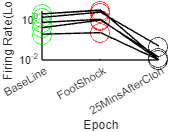

epochs = ["BaseLine", "FootShock", "25MinsAfterClon"];
figure;
hold on;
%  Create scatter plots for each epoch
scatter(ones(size(clonSensitive, 1), 1), clonSensitive.BLFR, 200, 'g', 'DisplayName', 'BL');  % Baseline
scatter(2 * ones(size(clonSensitive, 1), 1), clonSensitive.FSFR, 200, 'r', 'DisplayName', 'FS');  % Foot Shock
scatter(3 * ones(size(clonSensitive, 1), 1), clonSensitive.ClonFR, 200, 'k', 'DisplayName', 'CLon5');  % Clonidine at 5 minutes

% Add lines connecting points of the same unitID
for i = 1:height(clonSensitive)
    xValues = [1, 2, 3];  % Corresponding to 'BL', 'FS', 'CLon5'
    yValues = [clonSensitive.BLFR(i), clonSensitive.FSFR(i), clonSensitive.ClonFR(i)];  % Firing rates for each epoch

    plot(xValues, yValues, 'k-');  % Connects points with a black line
end
set(gca, 'xtick', 1:3, 'xticklabel', epochs);
xlabel('Epoch');

% Y-axis
ylabel('Firing Rate(Log)');
set(gca, 'YScale', 'log');
ylim([min(clonSensitive.ClonFR), max(clonSensitive.FSFR)]); % Set y-limits based on your data range
%title('Scatter Plot of Firing Rate by Epoch');
hold off;

# Pull rows of clon sensitive units

% Find matching rows
matchingRows = ismember(Data.unitID, clonSensitive.unitID);

% Extract rows from data
clonSenSpikes = Data(matchingRows, :);

# RasterPlotForClonSensitive

result = clonSenSpikes;
figure;
hold on;

uniqueUnits= unique(Data.unitID);
countUnits=length(uniqueUnits)+1;
line([blDone,blDone], [1,countUnits], 'Color', 'g', 'LineWidth', 1.5);
line([FsStart,FsStart], [1,countUnits], 'Color', 'r', 'LineWidth', 1.5);
line([FsDone,FsDone], [1,countUnits], 'Color', 'r', 'LineWidth', 1.5);
line([ClonInject,ClonInject], [1,countUnits], 'Color', 'k', 'LineWidth', 1.5);
line([clon30,clon30], [1,countUnits], 'Color', 'k', 'LineWidth', 1.5);

% Loop through the unique units and plot the raster for each unit
for i = 1:length(uniqueUnits)
    unitRows = result.unitID == uniqueUnits(i);
    unitTimestamp = result.timestamp(unitRows)/60; %convert to minutes
  
    % Plot spikes for the current unit
    softBlue = [0 0.4470 0.7410];
    scatter(unitTimestamp, ones(size(unitTimestamp))*i, 200, softBlue, 'Marker', '|', 'SizeData', 20);
end

% Set the x-axis limits to extend the range (adjust these values as needed)
xMin = 0; % Minimum x-axis value
xMax = 80; % total length of recording 

% Set the x-axis limits
xlim([xMin, xMax]);

% Set plot labels and title
xlabel('Time(min)');
ylabel('Unit');
title('Unit Firing Across Time');


yticks(1:length(uniqueUnits));
yticklabels(arrayfun(@num2str, uniqueUnits, 'UniformOutput', false));

% Invert y-axis to have the first unit at the top
set(gca, 'YDir', 'reverse');


% Show the plot
hold off;


Whole Raster Plot


figure;
hold on;

% Add a line for clonidine injection  on the X-axis
uniqueUnits= unique(Data.unitID);
countUnits=length(uniqueUnits)+1;
line([blDone,blDone], [1,countUnits], 'Color', 'g', 'LineWidth', 1.5);
line([FsStart,FsStart], [1,countUnits], 'Color', 'r', 'LineWidth', 1.5);
line([FsDone,FsDone], [1,countUnits], 'Color', 'r', 'LineWidth', 1.5);
line([ClonInject,ClonInject], [1,countUnits], 'Color', 'k', 'LineWidth', 1.5);
line([clon30,clon30], [1,countUnits], 'Color', 'k', 'LineWidth', 1.5);

% Loop through the unique units and plot the raster for each unit
for i = 1:length(uniqueUnits)
    unitRows = Data.unitID == uniqueUnits(i);
    unitTimestamp = Data.timestamp(unitRows)/60; %convert to minutes
  
    % Plot spikes for the current unit
    softBlue = [0 0.4470 0.7410];
    scatter(unitTimestamp, ones(size(unitTimestamp))*i, 200, softBlue, 'Marker', '|', 'SizeData', 20);
end

% Set the x-axis limits to extend the range (adjust these values as needed)
xMin = 0; % Minimum x-axis value
xMax = clon30; % total length of recording 

% Set the x-axis limits
xlim([xMin, xMax]);

% Set plot labels and title
xlabel('Time(min)');
ylabel('Unit');
title('Unit Firing Across Time');


yticks(1:length(uniqueUnits));
yticklabels(arrayfun(@num2str, uniqueUnits, 'UniformOutput', false));

% Invert y-axis to have the first unit at the top
set(gca, 'YDir', 'reverse');


% Show the plot
hold off;

Bursts

units = unique(clonSenSpikes.unitID);
minBurstISI = 0.08;
maxBurstISI = 0.16;

burstvars = ["Unit", "Burst", "StartTime", "StopTime", "Duration", 'InterburstInterval', "NumSpikes", "FiringRate", "ISIinBurst"];
burst = table('Size', [0, length(burstvars)], 'VariableTypes', repmat("double", 1, length(burstvars)), 'VariableNames', burstvars);

for i = 1:length(units)
    unitdata = clonSenSpikes(clonSenSpikes.unitID == units(i), :);
    burstIdxs = [];
    inburst = false;
    for j = 1:height(unitdata)
        if j > 1
            prevISI = unitdata.timestamp(j) - unitdata.timestamp(j-1);
        else
            prevISI = Inf;
        end
        if j < height(unitdata)
            nextISI = unitdata.timestamp(j+1) - unitdata.timestamp(j);
        else
            nextISI = Inf;
        end

        if (prevISI > minBurstISI) && (nextISI < minBurstISI)
            burstIdxs(end+1, 1) = j;
            inburst = true;
        elseif inburst && (prevISI < maxBurstISI) && (nextISI > maxBurstISI)
            burstIdxs(end, 2) = j;
            inburst = false;
        end
    end

    burstIdxs = burstIdxs(diff(burstIdxs,[],2) > 1,:);

    for j = 1:size(burstIdxs, 1)
        newEntry = table(units(i), j, unitdata.timestamp(burstIdxs(j,1)), unitdata.timestamp(burstIdxs(j,2)), ...
                         unitdata.timestamp(burstIdxs(j,2)) - unitdata.timestamp(burstIdxs(j,1)), NaN, ...
                         burstIdxs(j,2) - burstIdxs(j,1) + 1, ...
                         (burstIdxs(j,2) - burstIdxs(j,1) + 1) / (unitdata.timestamp(burstIdxs(j,2)) - unitdata.timestamp(burstIdxs(j,1))), ...
                         mean(diff(unitdata.timestamp(burstIdxs(j,1):burstIdxs(j,2)))), ...
                         'VariableNames', burstvars);
        if j < size(burstIdxs, 1)
            newEntry.InterburstInterval = unitdata.timestamp(burstIdxs(j+1, 1)) - unitdata.timestamp(burstIdxs(j,2));
        end
        burst = [burst; newEntry];
    end
end
